# Getting started -----------------------------------------------------------------------------------------------------------

## Stability selection overview

Algorithms that encourage sparsity in the feature space tradeoff stability, complicating the process of feature selection. Predictive models more generally sacrifice stability in estimated feature importance (i.e., parameter estimates) in order to achieve better generalizability. Stability selection is a framework that can wrap around any algorithm used to select or rank features in order to retrieve a set of features from your data in X that are more consistently related to your response variable y across many different perturbed versions of X. The hope is that by performing such a stability analysis beforehand, you can inject more consistency into your predctive model, constraining it to operate over features that you have evidence for being more stable.

The stabSel package performs stability selection. You can use it to determine which variables predict y using something simple, like correlation, or using something more complex, like an adaptive elastic net or a random forest. Either way, the strength of stabSel is that it selects a set of features that best predict y in a more generalizable and precise way than possible when running your feature selection method just once on your entire training dataset. In addition, stability selection lets us control the number of false positives in the set of features we deem to be important (also sometimes referred to as "stable" or "consistent" features). This is nice because while stabSel was created to generally facilitate reducing the number of features that would enter a predictive model, it also allows us to directly discover features that consistently predict our response variable in a significant way, letting us assign p-values to associations between the response variable and our features that were mapped using algorithms that don't traditionally permit us to do this kind of statistical testing. For example, this lets us assign p-values to features discovered to be important using out-of-bag error in a random forest, which can detect both nonlinear and linear relationships. 

The documentation in stabSel can give you a better sense of what it can do--there are lots of bells and whistles, and arguably lots of options you can set that the vast majority of users would never care about (and which should not make much difference to the results). It's also important to keep in mind that like any method, stability selection is not a panacea so please keep in mind that it is not guaranteed to improve your results. For example, it *can* be easy to overfit your data if you do not have many samples and the relationships in the data happen to be very complex, leaving you with a set of "stable" features identified in a training dataset that would have never been selected if the test data were used instead. This is not to say that stability selection does not improve models when sample sizes are low, but that there is no guarantee of improvement. See Tutorial2.mlx for a relevant example of some of these caveats, where stabSel makes a huge difference for some algorithms but not others when predicting dementia risk from a discourse measures. 

## Getting started with some toy data

Below are some examples showing you how to use stabSel for regression. If you are interested in classification, all of the examples will provide a good starting point. You can recycle the code and replace the regression models built after stabSel with your own algorithm of choice. You can select a classification algorithm to use within stabSel by consulting the stabSel.m documentation. 

I've uploaded a toy dataset for us to work with here: [https://drive.google.com/file/d/1nUSnseZHNdpDG-UXGhFNvZNaydlLg3LN/view?usp=sharing](https://drive.google.com/file/d/1nUSnseZHNdpDG-UXGhFNvZNaydlLg3LN/view?usp=sharing)

First, download that dataset and copy it into the folder that contains the StabilitySelection repository:

copyfile('~/Downloads/stabSelToy.mat','~/Downloads/StabilitySelection-main/') % you may have to change this to whatever folder contains stabSel)

Now let's navigate to the directory that contains StabilitySelection (e.g., cd('~/Downloads/StabilitySelection-main/')) and load up the toy dataset.

cd('~/Downloads/StabilitySelection-main/') % you may have to change this to whatever folder contains stabSel
clear; load stabSelToy

As a disclaimer, this dataset was selected quasi-randomly from the UCI machine learning repository. The variables are strongly intercorrelated and the number of samples is massive, which is not ideal for showing how effective stabSel can be (it shines when there are many noisy features that can be pruned and when perturbing the dataset has a strong effect). In any case, the examples show you how to use stabSel and help demonstrate its value.

Once you've loaded in the dataset, you should see an X and y variable in the workspace. X contains a subset of the million song database. Every row in X is a different song, and every column is a feature related to timbre (e.g., covariance). We would like to know if we can use information about timbre to predict the year in which a song was produced. Song years are stored in a single column in y. For the purposes of these example analyses, we don't care about precisely interpreting our features. If you want to know more about the dataset we'll be using, you can find more info here: [http://archive.ics.uci.edu/ml/datasets/YearPredictionMSD#](http://archive.ics.uci.edu/ml/datasets/YearPredictionMSD#)

When using stabSel on your own data, make sure that features are stored in the columns of X, and that rows of X and y correspond to samples (y should have 1 single column). The minimum input variables stabSel needs to function are X and y. For example, you can run stabSel just like this:

%[fk,fsc,fscmx,maxVars,alpha,lam,scores,oid,ctr,mdlO,ep,empMaxVars,thresh,numFalsePos] = stabSel(X,y);

However, the code above might not give you the results you are looking for as it will apply a very stringent threshold to the feature selection process (as the examples below illustrate in more detail).

**NOTE: Example 1 is simple but covers a lot of important considerations, especially proper setup of cross-validation. Consider looking over this example even if it is less relevant than the others. The cross-validation section in particular has been highlighted. Cross-validation is misspecified remarkably often in studies and it is important that feature selection does not leak data into the test set that you will use to establish model performance. **

# Example 1: Reducing the feature set when building a predictive model ------------------------------------------------------------------

This is the example that stabSel was initially written in mind with. Let's say we want to build a model to predict song year, but we have much too many features than we can work with--maybe thousands. If the samples in our model approach or exceed the number of features that we have, then our model would likely benefit from feature reduction.

If our goal is to simply reduce feature size and not to precisely define the measured properties of timbre that significantly predict song year, then we can use stabSel in a relatively blunt way. This is what we will do in this example, folding stability selection into a cross-validation scheme for testing the ability of a linear regression model to predict song year. 

## Basic resampling, feature selection, and probability threshold options in stabSel

The core idea in stability selection is to resample your data many times, each time forcing a feature selection method to select some number of most important features for predicting y. Looking over these many resampled datasets, we can then compute the probability that a feature was selected. If the probability is high enough, we then add that feature to a set of "stable" features that are more consistently selected across perturbed versions of our dataset. Typically, we resample 50% of the dataset, but in some cases it may make sense to resample more or less of the data. For example, in the case that sample size is very small, resampling more of the data can improve stability selection but may upset the equations that we use for correcting false positives in our stable set (more on that later). To change any option in stabSel, like the proportion of data resampled, we add that option to our call to stabSel, like so: 

%[fk,fsc,fscmx,maxVars,alpha,lam,scores,oid,ctr,mdlO,ep,empMaxVars,thresh,numFalsePos] = stabSel(trX,trY,'samType','bootstrap');

The initial paper to propose stability selection advocated for sampling without replacement. Some folks since then have advocated for sampling with replacement, although these two options are effectively interchangeable for certain resampling proportions (see stabSel.m). We can also create complementary pairs of samples to reduce the number of resamples that we need to take in order to get a good estimate of feature selection probability. However, keep in mind that this is advocated for in the context of sampling with replacement. 

#### Setting up our options for stabSel

In this example, we'll stick with the resampling technique from the original stability selection proposal: subsampling without taking complementary pairs of subsamples (controlled by 'samType' option). We'll repeat our subsampling procedure only 50 times to keep the analysis quick (controlled by 'prop'), but you should increase this number to something more reasonable when analyzing your own data (e.g., 500). For selecting our features, we will use a very simple and fast method: correlation (controlled by 'selAlgo' option). This means that in each subsample, we will correlate the response variable with each feature. We will then force the selection method to remove ~80% of our features (controlled by 'maxVars' option). We will deem any feature that is selected in at least half of the subsamples as 'stable'. A lower threshold here makes some sense given that it will be hard for correlation to rank our features well (i.e., they're all strongly intercorrelated and so less likely to be consistently selected across subsamples). 

#### Some important considerations

Using stability selection purely for feature discovery is complicated. We'll get more into the details of why that is the case later, but the gist is that the familwise error correction that is applied is generally very stringent. The best way to loosen these thresholds is currently being worked out. For example,

- Complementary bootstraps may provide a way to tighten the bounds for false positives: Shah, R. D., & Samworth, R. J. (2013). Variable selection with error control: another look at stability selection. *Journal of the Royal Statistical Society Series B: Statistical Methodology*, *75*(1), 55-80.

- Introducing permutations into the frameowrk may provide a way to measure FDR instead: Ahmed, I., Hartikainen, A. L., Järvelin, M. R., & Richardson, S. (2011). False discovery rate estimation for stability selection: application to genome-wide association studies. *Statistical applications in genetics and molecular biology*, *10*(1).

- Introduction of boosting may have a similar effect: Hofner, B., Boccuto, L., & Göker, M. (2015). Controlling false discoveries in high-dimensional situations: boosting with stability selection. *BMC bioinformatics*, *16*, 1-17.

At the same time, deviation from the standard settings explored by Meinshausen and Bühlmann was originally thought not to have a substantial impact on error control, but this might not necessarily be the case. For example, subsampling a larger portion of your dataset may break assumptions being made to ensure FWER. stabSel will warn you when this happens, however, what this ultimately means is that any p-values that are retrieved outside of certain settings should be considered with caution. Given that more false positives may be slipping through when we relax the stringency with which stabSel selects features, it is beneficial to evaluate these features on out-of-sample data that stabSel has not seen. It is worth pointing out that even when stabSel uses a stringent FWER under normal conditions to return features we can be confident are not false positives, it may be beneficial to evalute these features on out of sample data. That's because:

- A feature can be related to the response variable but not necessarily predictive in a particular model or dataset (e.g., the algorithm being used to select features)

- A stable feature is not necessarily relevant and may be consistently selected due to confounding factors or biases in the data

For this reason, most of the example sections will use stability selection in a cross validation scheme, where the stable features can be ensured to have predictive value within a different model. 

#### Setting up a cross-validation scheme 

In the current example, we want to know how well our model predicts our response variable. Let's set up an 8-fold CV scheme, which will allow us to evaluate the model we train on data that it has not seen, giving us a more realistic estimate of its performance. We will also fix the random number generator so that the results of this example are a bit more replicable. Your results will still vary, however. There are lots of stochastic elements involved. 

rng('default'); rng(1); % here we initialize a repeatable number generator with a seed of 1
c = cvpartition(length(y),'Kfold',8); % this is a structure that contains our folds

The code below can be recycled to set up a CV scheme outside of stabSel so feel free to reuse it for your purposes. Later on, we'll see how to setup nested CV schemes, which are more strongly recommended if the predictive model you are building has hyperparameters that need to be set. It's difficult to overstate how important it is that CV is applied properly in any analysis, especially when feature selection is involved. 

As a cautionary note, many meta-analyses and reviews have uncovered a substantial number of studies that misuse CV, resulting in data leakage that artificially inflates model performance. This is widespread across many fields and we will go through a followup example that will demonstrate just how insidious improperly setup CV schemes can be.

## Testing stabSel model using out of sample data

Now we will loop through our test folds. For each fold, we will find all of the samples of our data that were *not* in the fold and use those samples to train two linear regression models. One model will be trained on all of the features stored in X. A second model will be trained on features selected by stabSel. Our goal will be to test whether reducing our feature set with stabSel will improve performance of the model on data it has never seen. Note also, we will plot the samples used in each fold to visualize the CV process, which ensures test and training data is always kept separate. Note, stabSel output will be printed to the live code section but we will visualize CV in an external figure because the live code updating process can be delayed for heatmaps and there is no way to replay the plotting as it occurs. 

cmap(1,:) = [1 1 1]; cmap(2,:) = [0.81 0.32 0.48]; % setup a colormap for some images that we will generate
teIda = [];

% start looping through our folds
for i = 1:c.NumTestSets 
    disp(['Working on test set ' num2str(i) ' of ' num2str(c.NumTestSets)])

    % Get train/test splits
    trId = training(c,i); % these are the indices of our test set for fold i
    teId = test(c,i); % these are the indices of our test set for fold i
    
    trX = X(trId,:); % this determines our training data for fold i
    trY = y(trId); % this determines our training responses for fold i
    teX = X(teId,:); % this determines our test data for fold i
    teY = y(teId); % this determines our test responses for fold i. 

    teIda = horzcat(teIda,teId); % concatenate test samples across folds for visualization

    if i == 1
        f = figure;
        set(f, 'Visible', 'on');
    end
    figure(f)
    h = heatmap(double(teIda'),'CellLabelColor','none','XDisplayLabels',NaN*ones(length(teId),1)); colormap(cmap);
    h.ColorbarVisible = 'off'; h.GridVisible = 'off'; set(gcf,'color','white'); h.FontSize = 6;
    title(['Working on outer fold: ' num2str(i) ' of ' num2str(c.NumTestSets) ' (red bars are test samples)']);
    ylabel('Outer Fold');
    
    % Run stability selection
    [fk,~,~,~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY,'selAlgo','corr',...
        'samType','subsample','rep',50,'compPars',false,'filter',true,'thresh',0.5,...
        'maxVars',round(size(trX,2)/6),'verboseFin',1); 
    % We use 'filter' in the call because correlation can be used as either
    % a filter for ranking variables, or to select significant variables on
    % each resample (by default stabSel has filter set to false because the
    % default selection algorithm does not make sense to use as a filter).
    % Note, there are two verbose settings in stabSel. 'verbose' true/false
    % determines whether very specific details about selection are
    % retrieved. 'verboseFin' independently controls the final summary
    % output (e.g., p-values, etc). Here we suppress the summaries to
    % better visualize CV as it occurs.

    % Train/test models
    mdl = fitrlinear(trX(:,fk),trY,'Learner','leastsquares'); % train stabSel augmented model using ridge regression

Working on test set 1 of 8


Number of features in the stable set: 15
Effective per-comparison error rate p-value is: 0.25
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.25
Effective per-family error rate p-value is: 1


Working on test set 2 of 8


Number of features in the stable set: 14
Effective per-comparison error rate p-value is: 0.25
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.25
Effective per-family error rate p-value is: 1


Working on test set 3 of 8


Number of features in the stable set: 14
Effective per-comparison error rate p-value is: 0.25
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.25
Effective per-family error rate p-value is: 1


Working on test set 4 of 8


Number of features in the stable set: 14
Effective per-comparison error rate p-value is: 0.25
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.25
Effective per-family error rate p-value is: 1


Working on test set 5 of 8


Number of features in the stable set: 14
Effective per-comparison error rate p-value is: 0.25
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.25
Effective per-family error rate p-value is: 1


Working on test set 6 of 8


Number of features in the stable set: 14
Effective per-comparison error rate p-value is: 0.25
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.25
Effective per-family error rate p-value is: 1


Working on test set 7 of 8


Number of features in the stable set: 14
Effective per-comparison error rate p-value is: 0.25
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.25
Effective per-family error rate p-value is: 1


Working on test set 8 of 8


Number of features in the stable set: 16
Effective per-comparison error rate p-value is: 0.25
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.25
Effective per-family error rate p-value is: 1


    yhat(test(c,i),1) = predict(mdl,teX(:,fk)); % test this model
    mdl = fitrlinear(trX,trY,'Learner','leastsquares'); % repeat processs without stabSel (ridge regression)
    yhat2(test(c,i),1) = predict(mdl,teX);

r1 = 0.1305

end

r2 = 0.1090

% evaluate performance

mse1 = 112.3724

ff = figure;

mse2 = 113.1402

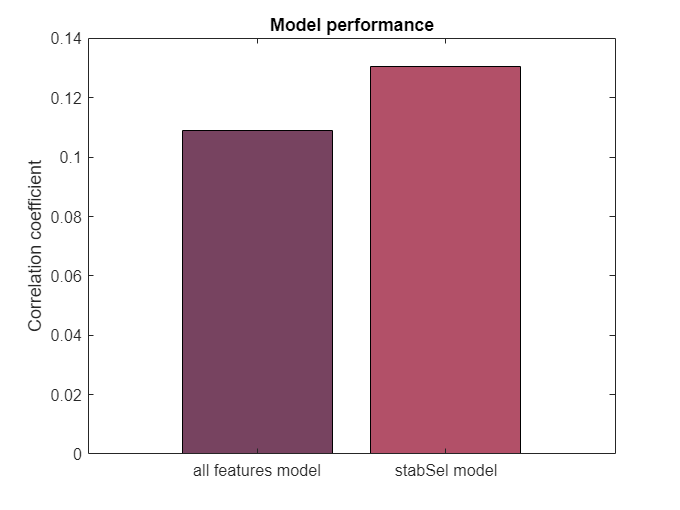

r1 = corr(y,yhat); % stabSel model
r2 = corr(y,yhat2); % model trained using all features
mse1 = mean((y-yhat).^2);
mse2 = mean((y-yhat2).^2);
disp(['correlation based performance for model with stabSel (using correlation as selection algo): ' num2str(r1)])
disp(['correlation based performance for model without stabSel (using all features): ' num2str(r2)])

disp(['mean squared error based performance for model with stabSel (using correlation as selection algo): ' num2str(mse1)])
disp(['mean squared error based performance for model without stabSel (using all features): ' num2str(mse2)])

% Create barcharts for performance
b=bar(categorical({'stabSel model','all features model'}),[r1 r2],'FaceColor','flat');

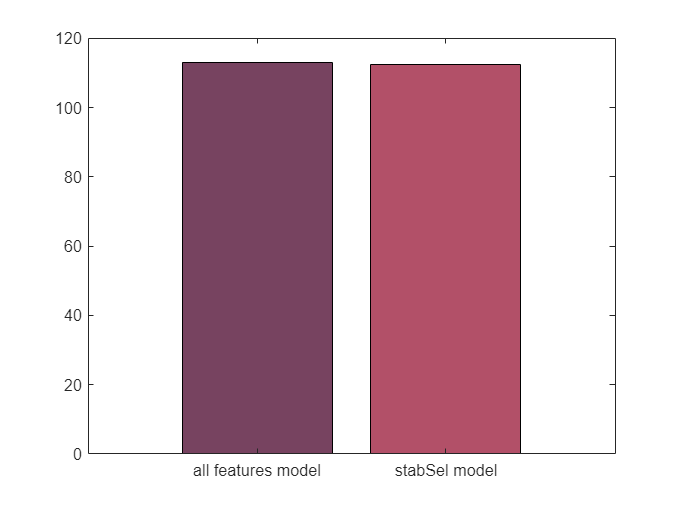

b.CData(1,:) = ([119 67 96])/255;
b.CData(2,:) = ([178 80 104])/255;
title('Model performance')

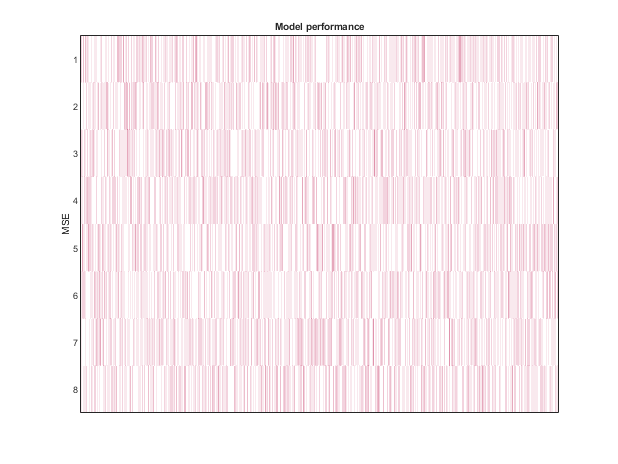

ylabel('Correlation coefficient')
b=bar(categorical({'stabSel model','all features model'}),[mse1 mse2],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;

b.CData(2,:) = ([178 80 104])/255;
%ylim([100 120])
title('Model performance')
ylabel('MSE')

How did the models do for you? On my end, the stabSel model's performance as measured by correlating predictions of song year with actual song year (in r1) was 0.1368. The model that used all features got an r-value of 0.109. This was consistent across ~20 repeats of the code above with shuffled rng so you should have also found better performance for the stabSel model (also true of mean squared error as stored in mse1 and mse1).  

You may have noticed stabSel displayed some other data each time it ran. For example, our effective FWER p-value was 1, which is the default and we did not change it. It amounts to the number of false positives we expect in our stable set. And that's okay as we were not attempting to put a p-value on our selected features. We can also see that the number of features that were in the stable set were ~15. That means that even though we forced the correlation method to select 15 features in each subsample, our probability threshold for the stable set ended up giving us 15 features in the stable set too. Returned also we have a PCER which tells us the most pessimistic rate for which, on average, we may be making a Type 1 error when testing a feature (not accounting for multiple comparisons). As you can see, under the *worst* case scenario, our stable features are mostly false positives. 

Again, the specific PCER may not matter to you if the goal is to simply reduce the feature space to a set of features that are informative and help stabilize a later model that you subsequently build.

One final note: we have a lot of samples but hopefully you can appreciate from the heatmap that updated with every tested fold that our test sets always used a unique slice of our dataset. To emphasize this point, we can take the sum of teIda, the variable we used to track which samples were used for testing. Since teIda contains a 1 for each of the 50,000 samples that were used as the test set, we can collapse across test sets for each sample. If we looked at the unique values in the resulting vector we should only ever see the value 1, which represents the total number of times that any sample was used as a test sample.

disp(['The numebr of times any sample was used for testing is: ' num2str(unique(sum(teIda')))])

The numebr of times any sample was used for testing is: 1


Unfortunately, these results also tell us that clearly we cannot predict song year from timbre very well using our linear regression model. Nevertheless, you can see that reducing our feature set helped us net a small increase in performance. But how would the model have done if we had run a simple correlation filter without stability selection?

for i = 1:c.NumTestSets 
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c.NumTestSets)])
    trX = X(training(c,i),:); % this determines our training data for fold i
    trY = y(training(c,i)); % this determines our training responses for fold i
    teX = X(test(c,i),:); % this determines our test data for fold i
    teY = y(test(c,i)); % this determines our test responses for fold i. 
    
    % Run correlation filter -- this is how correlation would be
    % used inside a subsample in stabSel as called in the last block of
    % code
    rtmp = corr(trX,trY);
    [~,idx] = sort(rtmp,'descend');
    fk = idx(1:15); % this is roughly the number of features stability selection selected for us on each fold

    % Train/test models
    mdl = fitrlinear(trX(:,fk),trY,'Learner','leastsquares'); % train filter augmented model
    yhat3(test(c,i),1) = predict(mdl,teX(:,fk)); % test this model
end

Working on test set 1 of 8
Working on test set 2 of 8
Working on test set 3 of 8
Working on test set 4 of 8
Working on test set 5 of 8
Working on test set 6 of 8
Working on test set 7 of 8
Working on test set 8 of 8


% evaluate performance
r3 = corr(y,yhat3) % filter model

r3 = 0.0990

mse3 = mean((y-yhat3).^2)

mse3 = 113.4743

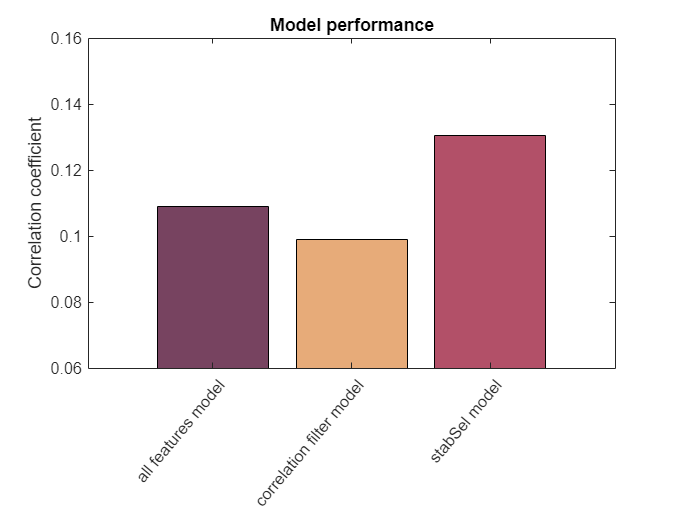

% Create barcharts for performance
b=bar(categorical({'all features model','correlation filter model','stabSel model'}),[r2 r3 r1],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(3,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
ylim([0.06 0.16])
title('Model performance')
ylabel('Correlation coefficient')
xtickangle(50)

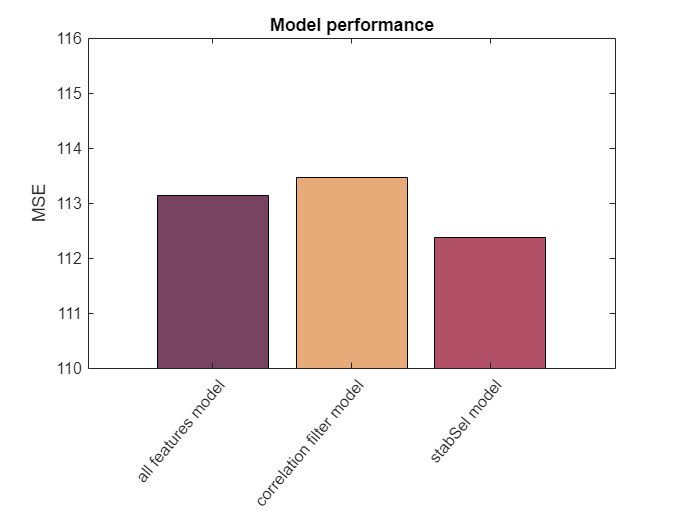

b=bar(categorical({'all features model','correlation filter model','stabSel model'}),[mse2 mse3 mse1],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(3,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
ylim([110 116])
title('Model performance')
ylabel('MSE')
xtickangle(50)

As you can probably see, repeating the filtering process over slightly different subsets of your data performs *much* better, helping to select features in a way that is less likely to lead to overfitting. In my case, r3 was 0.0986 for the model above (and mse2 was also much lower than mse3). Stability selection works!

I will end this example on one final point to help you use stabSel in the way we have above. In this example, we have selected some options in stabSel (e.g., 'thresh', 'maxVars') based on the qualities of our data, but also in some arbitrary ways. Exactly how much you want to shrink your feature space is a subjective question that can be controlled by manipulating *both* thresh and maxVars. If I want stabSel to return exactly 15 features in the stable set, I can either choose an arbitrary maxVars and dial in the threshold until I get to that many features, or I can go in the other direction and choose an arbitrary threshold and dial in maxVars. The angle this problem is approached from shouldn't really matter. In fact, for stability selection with lasso, changing 'thresh' at all has been suggested not to influence the results very much (at least when maxVars is estimated to ensure <1 false positive as discussed in the next example). Lastly, I want to mention you probably shouldn't be using correlation as your feature selection method:) It sure is fast, but stabSel can do a lot more.

# Example 1.5: The dangers of data leakage ---------------------------------------------------------

In the previous example, we went throught the process of separating our training and test data such that our model is always tested on data that it has not seen. If the data is manipulated in any way before it is partitioned for cross-validation, we run the risk of leaking information about the training data into our test set. We want to avoid this at all costs as it will massively inflate our models' performance and make evaluating models impossible. After all, we are essentially letting our model cheat by letting it see something about the test data during training. 

Data leakage is unfortunately common in the machine learning literature, and in the majority of cases, fixing it deflates many of the conclusions of studies. There are a ton of really great meta-analyses that have noticed this, but for starters I will point you to this excellent meta-study from last year by Sayash Kapoor and Arvind Narayanan at Princeton University:  [https://arxiv.org/pdf/2207.07048.pdf.](https://arxiv.org/pdf/2207.07048.pdf.) I think this paper does an incredible job of pointing to many previously published meta-analyses and highlighting the pervasiveness of this issue and its impact.

So what specifically should we be careful about when trying to avoid data leakage? Well, basically anything! Everything we do can be nested inside cross-validation loops. Arguably, even the phenomenon of p-hacking is a kind of pesky overfitting that results from data leakag (see Yarkoni, T., & Westfall, J. (2017). Choosing prediction over explanation in psychology: Lessons from machine learning. *Perspectives on Psychological Science*, *12*(6), 1100-1122.). By always reserving external out-of-sample data for validating analysis decisions, we can help guard against this kind of overfitting. 

More common forms of data leakage occur when, for example, data imputation or normalization occurs prior to cross-validation. It also includes dimensionality reduction (think PCA) prior to cross-validation. More crucially for this tutorial, ***any*** kind of feature selection prior to cross-validation counts as well. 

Let's look at what might happen if we perform feature selection before cross-validation. Now, if you use the previous stabSel example, you will find some evidence of overfitting. But let me show you how bad it can get using the ver last example, where we used a correlation filter. To make the overfitting much worse we will do the following: 1) remove 450/500 samples (smaller samples produce less stable performance estimates), 2) select only the top 5 correlations (higher correlations in smaller samples are probably going to be more susceptible to outliers).

Xtmp = X(1:50,:); % here we will remove all samples except the first 50
ytmp = y(1:50); % repeat for our response variable

% to overfit on purpose, we will do feature selection before CV
rtmp = corr(Xtmp,ytmp);
[~,idx] = sort(rtmp,'descend');
fk2 = idx(1:5); % pull out the top 5 features

% since we have changed the samples, we need to redefine our CV scheme. We
% will use fewer folds here to accentuate the overfitting
c2 = cvpartition(length(ytmp),'Kfold',5);

clear yhat3 yhat4 % this is to clear previous data we will overwrite (it had more samples)
for i = 1:c2.NumTestSets
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c.NumTestSets)])
    trX = Xtmp(training(c2,i),:); % this determines our training data for fold i
    trY = ytmp(training(c2,i)); % this determines our training responses for fold i
    teX = Xtmp(test(c2,i),:); % this determines our test data for fold i

    % using the correlation filter here again, but now without leakage
    rtmp = corr(trX,trY);
    [~,idx] = sort(rtmp,'descend');
    fk = idx(1:5); % take the top 5 features sorted by correlation

    % Train/test models
    mdl = fitrlinear(trX(:,fk),trY,'Learner','leastsquares'); % train no data leakage model
    yhatNDL(test(c2,i),1) = predict(mdl,teX(:,fk)); % test the no data leakage model

    mdl = fitrlinear(trX(:,fk2),trY,'Learner','leastsquares'); % train data leakage model
    yhatDL(test(c2,i),1) = predict(mdl,teX(:,fk2)); % test the data leakage model
end

Working on test set 1 of 8
Working on test set 2 of 8
Working on test set 3 of 8
Working on test set 4 of 8
Working on test set 5 of 8


% evaluate performance
rndl = corr(ytmp,yhatNDL) % no data leakage model

rndl = 0.0694

rdl = corr(ytmp,yhatDL) % data leakage model

rdl = 0.5282


msendl = mean((ytmp-yhatNDL).^2) % no data leakage

msendl = 11.9254

msedl = mean((ytmp-yhatDL).^2) % data leakage model

msedl = 9.2618

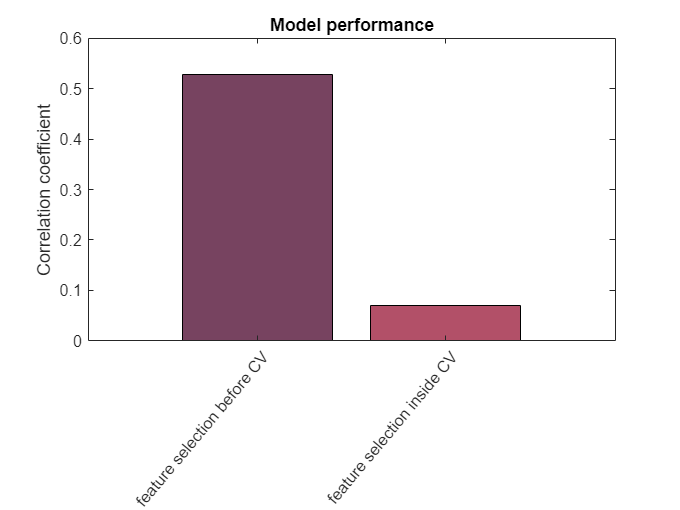


% Create barcharts for performance
b=bar(categorical({'feature selection inside CV','feature selection before CV'}),[rndl rdl],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(2,:) = ([178 80 104])/255;
title('Model performance')
ylabel('Correlation coefficient')
xtickangle(50)

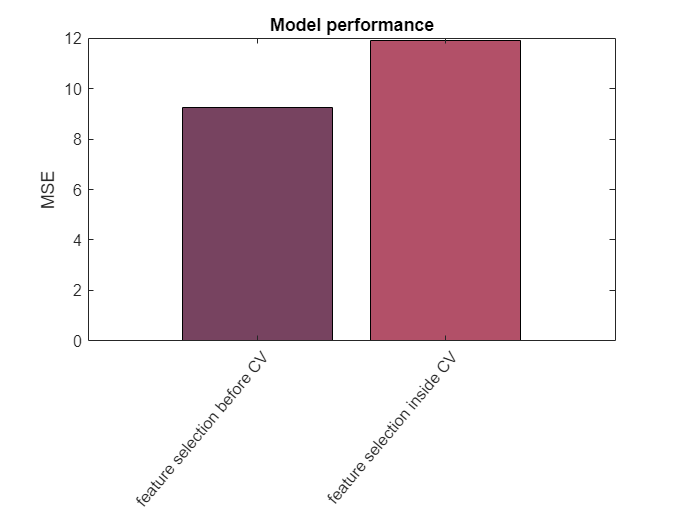

b=bar(categorical({'feature selection inside CV','feature selection before CV'}),[msendl msedl],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(2,:) = ([178 80 104])/255;
title('Model performance')
ylabel('MSE')
xtickangle(50)

As you can see, running stabSel before CV can be disastrous. For example, here, I have a correlation coefficient difference of ~0.4 (0.06 for no data leakage model and 0.5 for the data leakage model. When you ran this, you may have gotten something a little bit less drastic. If so, I would encourage you to rerun this code section. Within a few additional runs you will find evidence of massive overfitting.

# Example 2: Discovering features that predict the response variable ----------------------------------------------------------------------

## Controlling the per family error rate

Maybe you're not so interested in using stability selection to reduce the feature set of a predictive model. Maybe you are more interested in finding out which features representative of timbre are significantly associated with the age in which a song was produced. Stability selection can be used in this case as well. For example, we might use something like this: 

[fk,fsc,fscmx,maxVars,alpha,lam,scores,oid,ctr,mdlO,ep,empMaxVars,thresh,numFalsePos] = stabSel(X,y,'selAlgo','corr',...
        'samType','subsample','rep',250,'compPars',false,'filter',true,'numFalsePos',1); 

Number of features in the stable set: 8
Effective per-comparison error rate p-value is: 0.45
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.45
Effective per-family error rate p-value is: 0.5


You can see the call above is almost identical to what we used in example 1, except now we have left off the 'thresh' and 'maxVars' options. You might be wondering how stabSel was able to produce any output given these omissions. Well that's because we've provided a number of false positives that we would like to try to ensure in our stable set. If we left 'numFalsePos' out of our call, stabSel would default to trying to ensure 1 false positive in our stable set. When omitting 'thresh' and 'maxVars' while using a filter method for feature selection, stabSel ensures the selected number of false positives by using a default 'thresh' value of 0.9 and selecting the appropriate number of maxVars using the following equation. This thresh value means that only features selected in 90%+ of resampled datasets enter the stable set.

So how do we do this? Well, critically, it turns out that we can estimate the (upper bound) of the expected number $V$ of falsely selected variables for 'thresh' values 0.5 through 1 using the following equation, where the empirical probability of a feature being selected ('thresh') is represented as $\pi \textrm{thr}$, the average number of features selected by the selection method ('empMaxVars', which is usually equal to 'maxVars') is represented by ${q\Lambda }$, and the number of features (size(X,2)) is represented by p:


$$E(V)\le \frac{1}{2\pi_{\mathrm{t}\mathrm{h}\mathrm{r}} -1}\frac{q_{\Lambda }^2 }{p}$$


What this means is that if we select some 'thresh' value to use, and a number of false positives that we would like to maintain, then we can compute the right 'maxVars' to use. This is provided that our feature selection method can guarantee the selection of a prespecified 'maxVars' number of variables (more on that later). Alternatively, we can work backwards to select 'thresh' from 'maxVars'. We work backwards when we cannot guarantee a certain number of 'maxVars'. This is the case when the number of surviving features is controlled by an opaque regularzation parameter that we do not have insight into.

Note that the number of false positives is equal to the per-family error rate, a correction that is stronger than FWER. That means we can set 'numFalsePos' to 0.05 if we would like. 

[fk,fsc,fscmx,maxVars,alpha,lam,scores,oid,ctr,mdlO,ep,empMaxVars,thresh,numFalsePos] = stabSel(X,y,'selAlgo','corr',...
        'samType','subsample','rep',250,'compPars',false,'filter',true,'numFalsePos',0.05); 

Number of features in the stable set: 7
Effective per-comparison error rate p-value is: 0.45
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.45
Effective per-family error rate p-value is: 0.05


Unfortunately, this only revealed a single significant feature. There are three reasons for this. Not only are we applying a stringent type of threshold, but also we are applying it in the context of a relatively stringent testing procedure. Further, we are using a relatively weak 'learner' or feature selection algorithm. Finally, this data is not well-suited for feature selection. Stability selection shines when p >> n, but also, this dataset has been already processed in a way that may not be ideal for feature selection (see concluding notes for more details; for the purposes of the tutorial we will ignore this).

By the way, you can check the way stabSel set all of our variables automatically by inspecting the relevant output variables. Note, fk contains the indices of the features that were retained in the stable set.

disp(['Number of features selected by feature selection method: ' num2str(maxVars)])

Number of features selected by feature selection method: 9


disp(['Threshold selected: ' num2str(thresh)])

Threshold selected: 0.9


disp(['Actual number of false positives in the stable set: ' num2str(numFalsePos)])

Actual number of false positives in the stable set: 0.05


disp(['Number of features in the stable set: ' num2str(length(fk))])

Number of features in the stable set: 7


Setting the PFER using 'numFalsePos' to be 0.05 or less will likely produce poor results in datasets with few samples, or datasets with a ton of colinearity. In empirical work testing stabSel, folks tend to use something like 1 or slightly more false positives. This has typically allowed for the retrieval of the correct signal variables without correction for multiple comparisons. When taking this approach, you should manually choose a 'numFalsePos' to ensure some kind of per-comparison error rate (e.g., if there is 1 false positive our of 1000 tests/total features, the per-comparison p-value is 1/1000). stabSel does return this per-comparison rate in the display for you, but you can compute it before starting stabSel yourself to dial in the 'numFalsePos' that gives you the p-value you are looking for. It is recommended you choose something much lower than 0.05 for this p-value. 

There is another way to improve stabSel for feature discovery if the standard PFER option does not work for your data. You can try to select a 'numFalsePos' that would make up less than 95% of your stable set. For example, if we know 'maxVars' before we start stability selection, changing the size of the stable set is trivial because we can apply different thresholds to the empirical feature selection probabilities in our dataset. This means we can preselect the proportion of the stable set we would feel comfortable being a false positive, and iteratively try different threshold values until we reach the proportion we would like (note, we actually set the ratio of false positives to the stable set in practice). 

I tend to think of this proportion as an "FDR-like p-value", which is returned on every stabSel call. FDR is the ratio of false positive results to the total number of positive test results. Stability selection tells us the upper bound on the number of false positives (i.e., noise variables) that we have made, but does not say anything about the number of true positives. In other words, this p-value assumes the stable set includes all of the "signal" feeatures/variables. The advantage to using this p-value is that it is more stringent than a per-comparison error rate.

Let's see how things change if we instead tell stabSel to choose our thresh and numFalsePos to maintain an FDR-like p < 0.05. Note, we have to feed stabSel an empty 'thresh' option to ensure it knows we don't want to use the default 0.9 (this is set as the default as it is the typically recommended value to begin with; see original stability selection paper). For now, we will use a maxVars of 5.

[fk2,fsc2,fscmx2,maxVars2,alpha2,lam2,scores2,oid2,ctr2,mdlO2,ep2,empMaxVars2,thresh2,numFalsePos2] = stabSel(X,y,'selAlgo','corr',...
        'samType','subsample','rep',50,'compPars',false,'filter',true,'fdr',0.05,'maxVars',5,'thresh',[]); 

Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.2497
Probability threshold for features to enter stable set was calculated to be: 1.0562
Number of features in the stable set: 0
Effective per-comparison error rate p-value is: 0.52811
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.52811
Effective per-family error rate p-value is: 0.2497


Looks like p < 0.05 caused the threshold for our stable set to be impossibly high (>100%!). We should lower our maxVars.

[fk2,fsc2,fscmx2,maxVars2,alpha2,lam2,scores2,oid2,ctr2,mdlO2,ep2,empMaxVars2,thresh2,numFalsePos2] = stabSel(X,y,'selAlgo','corr',...
        'samType','subsample','rep',50,'compPars',false,'filter',true,'fdr',0.05,'maxVars',2,'thresh',[]); 

Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.099701
Probability threshold for features to enter stable set was calculated to be: 0.72289
Number of features in the stable set: 2
Effective per-comparison error rate p-value is: 0.36144
Per-comparison worst case scenario is that this many features in the stable set are false positives: 0.36144
Effective per-family error rate p-value is: 0.099701


By forcing our selection method to select fewer features, we were able to lower the 'thresh' necessary to achieve p < 0.05. Notice that the features in the stable set fk2 overlap with the features in fk. Given that we used stability selection to achieve this result rather than, for example, running correlations on the entire dataset, we expect these features to generalize much better. If we had run a correlation, we would have seen that most features significantly correlate with y despite being unable to predict it.

[rtmp,ptmp] = corr(X,y);
disp(['Correlation shows ' num2str(length(find(ptmp(:) < 0.05))) ' features out of ' num2str(length(ptmp)) ' are significantly associated with y'])

Correlation shows 81 features out of 90 are significantly associated with y


# An important caveat

If you use this fdr-like p-value it is critical for you to keep in mind that this is ***NOT *****an actual FDR value**, the name is only meant to help conceptualize what this value reflects. FDR is concerned with the proportion of false discoveries among all discoveries. But this "FDR-like p-value" is a measure of the proportion of expected false positives in a stable set, under the assumption that this set contains **ALL** relevant features. 

As a final note on the topic of p-values, the per-comparison error rate p-value is simply PFER divided by 2 as suggested by the original stability selection paper.

# Example 3: Parsimonious models ------------------------------------------------------------------------------------------------------------------

What if we wanted to build a predictive model that was also comprised of significant features? No problem! We would fold example 2 and example 1 together as shown below. While we're doing this, let's see how stabSel feature selection compares to simply using lasso to shrink some features to zero. We will give LASSO a fighting chance by tuning the lambda parameter inside a nested cross-validation scheme (i.e., a set of 4 inner folds). 

for i = 1:c.NumTestSets 
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c.NumTestSets)])
    trX = X(training(c,i),:); % this determines our training data for fold i
    trY = y(training(c,i)); % this determines our training responses for fold i
    teX = X(test(c,i),:); % this determines our test data for fold i
    teY = y(test(c,i)); % this determines our test responses for fold i. 
    
    % Run stability selection
    disp('Running stability selection')
    [fk,~,~,~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY,'selAlgo','corr',...
        'samType','subsample','rep',50,'compPars',false,'filter',true,'numFalsePos',1,'maxVars',4,'thresh',[]);  % we increase maxVars to 4 here but this will still produce non-empty stable sets
    % We use 'filter' in the call because correlation can be used as either
    % a filter for ranking variables, or to select significant variables on
    % each resample (by default stabSel has filter set to false because the
    % default selection algorithm does not make sense to use as a filter).

    % Train/test models
    disp('Fitting/testing regression model using stable set of features')
    mdl = fitrlinear(trX(:,fk),trY,'Learner','leastsquares'); % train stabSel augmented model
    yhat(test(c,i),1) = predict(mdl,teX(:,fk)); % test this model
    
end

Working on test set 1 of 8


Running stability selection


Probability threshold for features to enter stable set was calculated to be: 0.58889
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.25. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Fitting/testing regression model using stable set of features


Working on test set 2 of 8


Running stability selection


Probability threshold for features to enter stable set was calculated to be: 0.58889
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.25. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Fitting/testing regression model using stable set of features


Working on test set 3 of 8


Running stability selection


Probability threshold for features to enter stable set was calculated to be: 0.58889
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.25. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Fitting/testing regression model using stable set of features


Working on test set 4 of 8


Running stability selection


Probability threshold for features to enter stable set was calculated to be: 0.58889
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.25. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Fitting/testing regression model using stable set of features


Working on test set 5 of 8


Running stability selection


Probability threshold for features to enter stable set was calculated to be: 0.58889
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.25. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Fitting/testing regression model using stable set of features


Working on test set 6 of 8


Running stability selection


Probability threshold for features to enter stable set was calculated to be: 0.58889
Number of features in the stable set: 3
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.25. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Fitting/testing regression model using stable set of features


Working on test set 7 of 8


Running stability selection


Probability threshold for features to enter stable set was calculated to be: 0.58889
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.25. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Fitting/testing regression model using stable set of features


Working on test set 8 of 8


Running stability selection


Probability threshold for features to enter stable set was calculated to be: 0.58889
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.25. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Fitting/testing regression model using stable set of features


% evaluate performance
r4 = corr(y,yhat)

r4 = 0.0961

mse4 = mean((y-yhat).^2)

mse4 = 112.9370

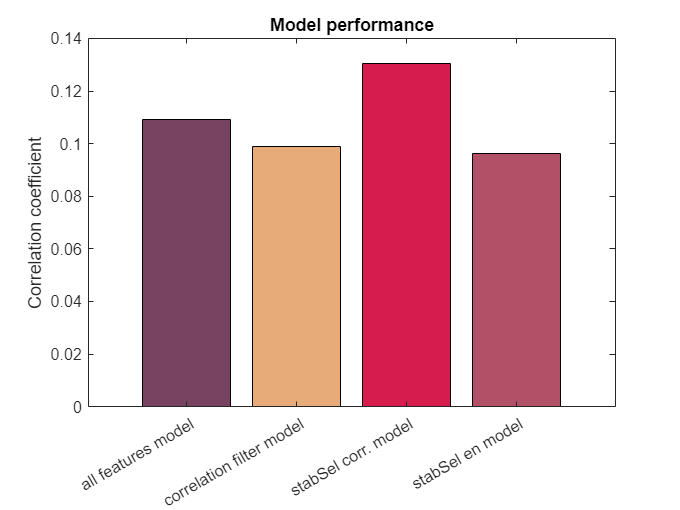

% Create barcharts for performance
b=bar(categorical({'all features model','correlation filter model','stabSel corr. model (lt 1 FalsePos)','stabSel corr. model (arbitrary)'}),[r2 r3 r4 r1],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(4,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
b.CData(3,:) = ([214 28 78])/255;
title('Model performance')
ylabel('Correlation coefficient')

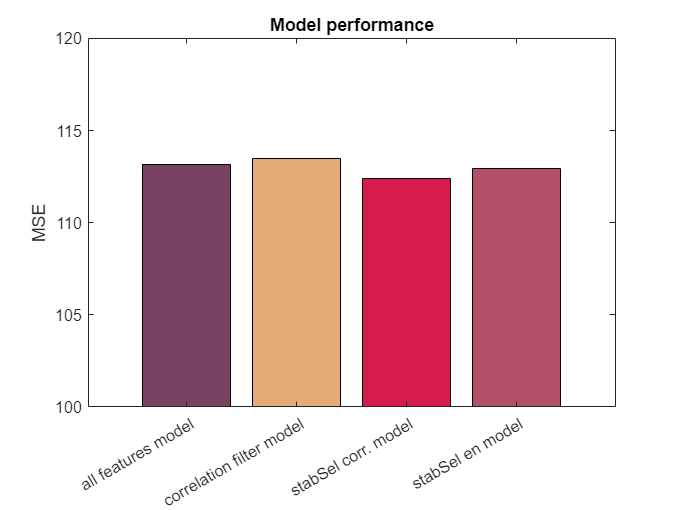

b=bar(categorical({'all features model','correlation filter model','stabSel corr. model (lt 1 FalsePos)','stabSel corr. model (arbitrary)'}),[mse2 mse3 mse4 mse1],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(4,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
b.CData(3,:) = ([214 28 78])/255;
ylim([100 120])
title('Model performance')
ylabel('MSE')

As you can see,the parsimonious model performs better than using all of the data, but not necessarily better than the arbitrary model we started out with. This represents some of the tension between maximizing predictability and the stringent statistical framework for error control in stability selection. However, the parsimonious model has several advantages. It performs nearly as well despite being much less complex, and it ensures that the features it relies on are both highly predictive of our response variable and statistically significantly associated with it. 

# Example 4: More complex feature selection with an elastic net ----------------------------------------------------------------------------

In the last example, we found our parsimonious model (~3 features) to achieve and r of ~0.12 and an mse of 112.68. Can we beat this using more complex methods for feature selection? Here, we will try an elastic net for choosing our features. This involves tuning two parameters during feature selection. To speed up the computational time, we will decrease the number of lambda (regularization) values that we will test, and we will also reduce the number of alpha values that we test (weighting of L1 to L2 norms). This reduction is relative to stabSel defaults, which requires passing in arguments to define lambdas and alphas. In addition, we will switch from subsampling to the more efficient complementary bootstrap method, which converges on stable features more quickly. The bootstrap method also results (theoertically) in less conservative selection. Note, however, that bootstrap stability selection has its own theorum for error control that is less stringent, but has not yet been implemented in stabSel. The standard error control from the original paper should be fine as it will always overestimate the number of false positives. Finally, in this example we will compare feature selection with an elastic net that is based on arbitrary variables to feature selection with error control. **WARNING: THIS EXAMPLE WILL STILL TAKE A SUBSTANTIAL AMOUNT OF TIME TO RUN.**

clear fk fk2 % we will index fk now...we will reuse the results in the next example so that we do not have to rerun it again...
for i = 1:c.NumTestSets 
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c.NumTestSets)])

Working on test set 1 of 8


Working on test set 2 of 8


Working on test set 3 of 8


Working on test set 4 of 8


Working on test set 5 of 8


Working on test set 6 of 8


Working on test set 7 of 8


Working on test set 8 of 8


    trX = X(training(c,i),:); % this determines our training data for fold i
    trY = y(training(c,i)); % this determines our training responses for fold i
    teX = X(test(c,i),:); % this determines our test data for fold i
    teY = y(test(c,i)); % this determines our test responses for fold i. 
    
    % Run stability selection -- *we will save the results so that we do
    % not have to regenerate them in the next example*
    [fk{i},~,~,~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY,'selAlgo','en',...
        'samType','bootstrap','rep',25,'compPars',true,'numFalsePos',0.05,'maxVars',...
        4,'thresh',[],'verbose',false,'ln',100,'alpha',[0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1],'fixMax',true); 

Empirical maxVars (actual average # of selected features across parameters) was: 0.88115
Probability threshold for features to enter stable set was calculated to be: 0.58627
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.056744. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 0.92594
Probability threshold for features to enter stable set was calculated to be: 0.59526
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.053999. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 0.87999
Probability threshold for features to enter stable set was calculated to be: 0.58604
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.056819. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 0.88087
Probability threshold for features to enter stable set was calculated to be: 0.58621
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.056762. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 0.89735
Probability threshold for features to enter stable set was calculated to be: 0.58947
Number of features in the stable set: 3
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.05572. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 0.87559
Probability threshold for features to enter stable set was calculated to be: 0.58518
Number of features in the stable set: 3
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.057104. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 0.88314
Probability threshold for features to enter stable set was calculated to be: 0.58666
Number of features in the stable set: 4
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.056616. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 0.88083
Probability threshold for features to enter stable set was calculated to be: 0.58621
Number of features in the stable set: 3
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.056764. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


    [fk2{i},~,~,~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY,'selAlgo','en',... % note, here we will use the same arbitrary variables we have used in previous examples...
        'samType','bootstrap','rep',25,'compPars',true,'filter',true,'thresh',0.5,...
        'maxVars',round(size(trX,2)/6),'verbose',false,'ln',100,'alpha',[0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1],'fixMax',true);

Empirical maxVars (actual average # of selected features across parameters) was: 2.711
Number of features in the stable set: 19
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 2.6655
Number of features in the stable set: 18
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 2.7546
Number of features in the stable set: 18
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 2.9315
Number of features in the stable set: 16
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 2.7853
Number of features in the stable set: 20
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 2.7828
Number of features in the stable set: 18
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 2.7538
Number of features in the stable set: 21
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Empirical maxVars (actual average # of selected features across parameters) was: 2.4906
Number of features in the stable set: 19
Effective per-comparison error rate p-value is: 0.5
Effective per-family error rate p-value is: 1
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


    % Train/test models
    mdl = fitrlinear(trX(:,fk{i}),trY,'Learner','leastsquares'); % train stabSel augmented model
    yhat(test(c,i),1) = predict(mdl,teX(:,fk{i})); % test this model
    mdl = fitrlinear(trX(:,fk2{i}),trY,'Learner','leastsquares'); % train stabSel augmented model
    yhat2(test(c,i),1) = predict(mdl,teX(:,fk2{i})); % test this model
end

% evaluate performance
r5 = corr(y,yhat) 

r5 = 0.1395

mse5 = mean((y-yhat).^2)

mse5 = 111.3401

r6 = corr(y,yhat2) 

r6 = 0.0983

mse6 = mean((y-yhat2).^2)

mse6 = 113.2057

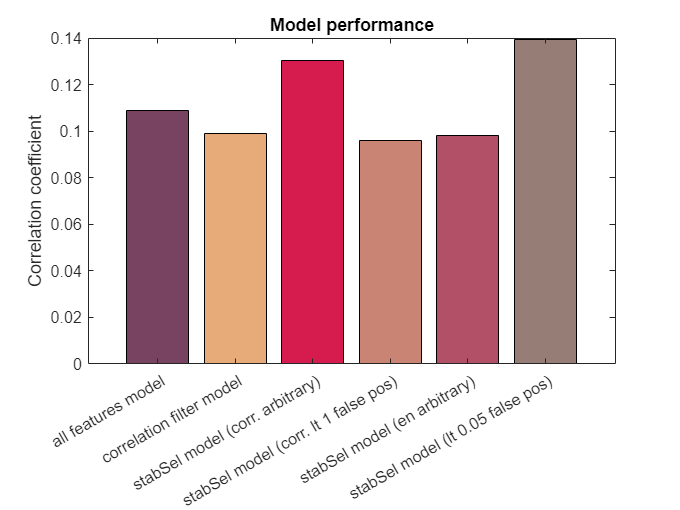

% Create barcharts for performance
b=bar(categorical({'stabSel model (corr. arbitrary)','all features model','correlation filter model','stabSel model (corr. lt 1 false pos)','stabSel model (lt 0.05 false pos)','stabSel model (en arbitrary)'}),[r1 r2 r3 r4 r5 r6],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(5,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
b.CData(3,:) = ([214 28 78])/255;
b.CData(6,:) = ([150 126 118])/255;
b.CData(4,:) = ([201 132 116])/255;
title('Model performance')
ylabel('Correlation coefficient')

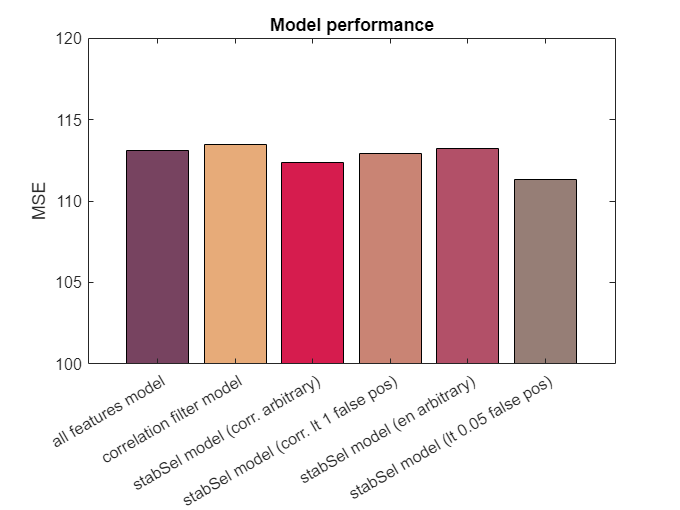

b=bar(categorical({'stabSel model (corr. arbitrary)','all features model','correlation filter model','stabSel model (corr. lt 1 false pos)','stabSel model (lt 0.05 false pos)','stabSel model (en arbitrary)'}),[mse1 mse2 mse3 mse4 mse5 mse6],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(5,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
b.CData(3,:) = ([214 28 78])/255;
b.CData(6,:) = ([150 126 118])/255;
b.CData(4,:) = ([201 132 116])/255;
ylim([100 120])
title('Model performance')
ylabel('MSE')

Looks like we can! When running this, I got a correlation value of 0.16 (c.f. 0.12 for correlation and 0.109 using all features) and a slightly lower MSE (110.9 vs 112.5 vs 113.1). Note that we would likely get better results if : i) we increased the range of parameters that we test closer to default values because we might be missing a parameter that gives us even more stable results, and ii) tried to build a more complex model AFTER feature selection. One remaining issue is that stability selection returned just a single feature for each fold, so while our model performs better, it's arguably too simple. We will address this in the next example.

# Example 5: Nested feature selection --------------------------

In the examples above, we did not bother to tune our ridge regression model. Whenever you tune any hyperparameters, it's important to create an independent set of folds. The fitrlinear.m model that we've been using for ridge regression is quite powerful. We can use some of its optional arguments to automatically generate 8 inner folds inside of each training dataset of the CV scheme we've already set up. We'll use simple grid search to tune our lambda parameter that controls the amount of regularization in our ridge model. 

for i = 1:c.NumTestSets 
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c.NumTestSets)])
    trX = X(training(c,i),:); % this determines our training data for fold i
    trY = y(training(c,i)); % this determines our training responses for fold i
    teX = X(test(c,i),:); % this determines our test data for fold i
    teY = y(test(c,i)); % this determines our test responses for fold i. 
    
    mdl = fitrlinear(trX(:,fk{i}),trY,'Learner','leastsquares','OptimizeHyperparameters','Lambda',...
        'HyperparameterOptimizationOptions',struct('Optimizer','gridsearch','MaxObjectiveEvaluations',20,'Verbose',0,'ShowPlots',false,'kfold',8)); % train stabSel augmented model
    yhatNest(test(c,i),1) = predict(mdl,teX(:,fk{i})); % test this model
end

Working on test set 1 of 8
Working on test set 2 of 8
Working on test set 3 of 8
Working on test set 4 of 8
Working on test set 5 of 8
Working on test set 6 of 8
Working on test set 7 of 8
Working on test set 8 of 8


%evaluate performance
r7 = corr(y,yhatNest) % stabSel model

r7 = 0.1488

mse7 = mean((y-yhatNest).^2)

mse7 = 111.0883

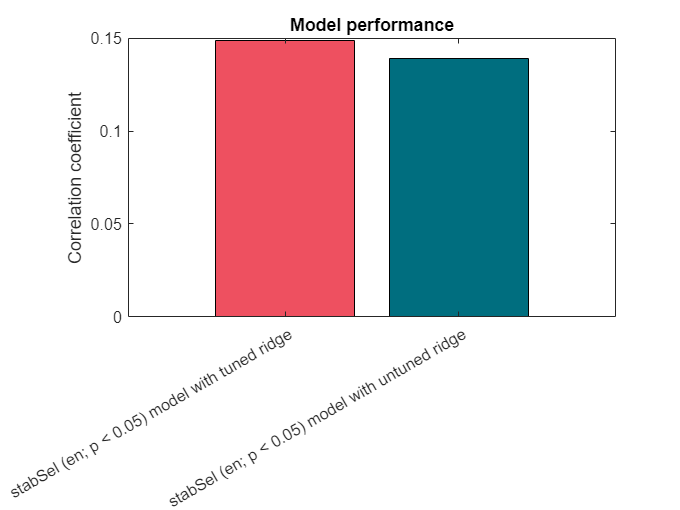

% Create barcharts for performance
b=bar(categorical({'stabSel (en; p < 0.05) model with untuned ridge','stabSel (en; p < 0.05) model with tuned ridge'}),[r5 r7],'FaceColor','flat');
b.CData(1,:) = ([238 80 96])/255;
b.CData(2,:) = ([0 110 127])/255;
title('Model performance')
ylabel('Correlation coefficient')

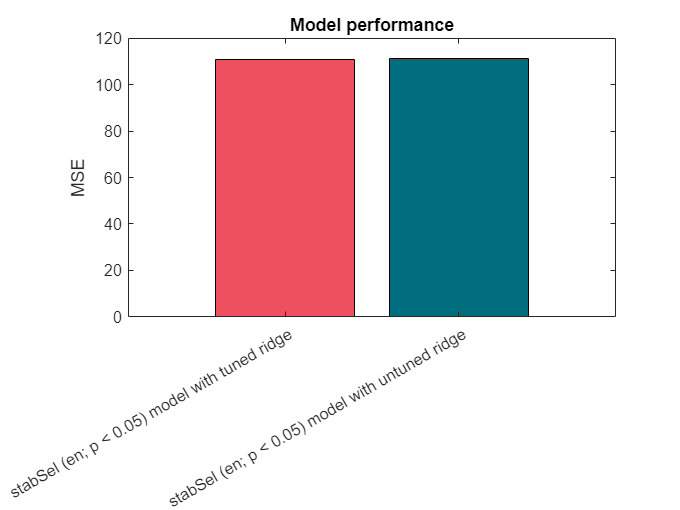

b=bar(categorical({'stabSel (en; p < 0.05) model with untuned ridge','stabSel (en; p < 0.05) model with tuned ridge'}),[mse5 mse7],'FaceColor','flat');
b.CData(1,:) = ([238 80 96])/255;
b.CData(2,:) = ([0 110 127])/255;
title('Model performance')
ylabel('MSE')

As you can see, tuning our predictive model using stability selection identified features produces an even more robust model!

# Example 6: Feature selection with adaptive elastic net/lasso ------------------------------------------------------------

stabSel can implement adaptive LASSO and adaptive EN, where we initialize EN or lasso with rdige regression weights (like a  warm-start). Adaptive LASSO improves the consistency of LASSO. It provides more consistant variable selection by regularization and is less sensitive to noise so its weights are more precise (e.g. lasso lacks "oracle" properties so we would not be necessarily perform as well if the correct model was known ahead of time). Adaptive lasso improves lasso--but can still encounter difficulties--when there are colinearities in the data or strong noise. For this reason, the adaptive elastic net has been proposed. Wrapping stability selection around the adaptive elastic net gives us the benefit of being able to test how well adaptive lasso/EN handles collinearities and noise. In practice, I often rely on the elastic net alone because the adaptive elastic net adds substantial computational time at the moment. Running this example will take quite some time! I'll be working to optimize the speed in a future update. For now, let's truncate our data to the first 100 samples.

X2 = X(1:100,:); % Even if we focus on the first 300 samples, this code will take a long time to run...be warned!
y2 = y(1:100);
c2 = cvpartition(length(y2),'KFold',8);
for i = 1:c2.NumTestSets 
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c2.NumTestSets)])
    trX = X2(training(c2,i),:); % this determines our training data for fold i
    trY = y2(training(c2,i)); % this determines our training responses for fold i
    teX = X2(test(c2,i),:); % this determines our test data for fold i
    teY = y2(test(c2,i)); % this determines our test responses for fold i. 
    
    % Run stability selection
    [fka{i},~,~,~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY,'selAlgo','en','adaptive',true,...
            'alpha',[0.1:0.1:1],'samType','bootstrap','rep',25,'compPars',true,'numFalsePos',0.05,'maxVars',...
            4,'thresh',[],'verbose',false,'ln',100,'fixMax',true); 
    
    % Train/test models
    mdl = fitrlinear(trX(:,fka{i}),trY,'Learner','leastsquares','OptimizeHyperparameters','Lambda',...
        'HyperparameterOptimizationOptions',struct('Optimizer','gridsearch','MaxObjectiveEvaluations',20,'Verbose',0,'ShowPlots',false,'kfold',8)); % train stabSel augmented model
    yhatNestA(test(c2,i),1) = predict(mdl,teX(:,fka{i})); % test this model
end

Working on test set 1 of 8


Empirical maxVars (actual average # of selected features across parameters) was: 1.2464
Probability threshold for features to enter stable set was calculated to be: 0.67261
Number of features in the stable set: 1
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.040116. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Working on test set 2 of 8


Empirical maxVars (actual average # of selected features across parameters) was: 1.7747
Probability threshold for features to enter stable set was calculated to be: 0.84995
Number of features in the stable set: 1
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.028174. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Working on test set 3 of 8


Empirical maxVars (actual average # of selected features across parameters) was: 1.7562
Probability threshold for features to enter stable set was calculated to be: 0.84271
Number of features in the stable set: 1
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.02847. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Working on test set 4 of 8


Empirical maxVars (actual average # of selected features across parameters) was: 1.3943
Probability threshold for features to enter stable set was calculated to be: 0.71602
Number of features in the stable set: 1
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.03586. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Working on test set 5 of 8


Empirical maxVars (actual average # of selected features across parameters) was: 1.4504
Probability threshold for features to enter stable set was calculated to be: 0.73373
Number of features in the stable set: 2
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.034474. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Working on test set 6 of 8


Empirical maxVars (actual average # of selected features across parameters) was: 1.0915
Probability threshold for features to enter stable set was calculated to be: 0.63237
Number of features in the stable set: 1
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.045809. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Working on test set 7 of 8


Empirical maxVars (actual average # of selected features across parameters) was: 1.3207
Probability threshold for features to enter stable set was calculated to be: 0.69381
Number of features in the stable set: 1
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.037858. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.


Working on test set 8 of 8


Empirical maxVars (actual average # of selected features across parameters) was: 1.527
Probability threshold for features to enter stable set was calculated to be: 0.75908
Number of features in the stable set: 1
Effective per-comparison error rate p-value is: 0.025
Effective per-family error rate p-value is: 0.05
Effective FDR-like p-value (INTERPRET WITH CAUTION NOT ACTUAL FDR) is: 0.032744. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.



% evaluate performance
r8 = corr(y2,yhatNestA) 

r8 = 0.4468

mse8 = mean((y2-yhatNestA).^2)

mse8 = 22.0074

So you can see this model performs incredibly well compared to our previous models! Unfortunately, however, it is also selecting just 1-2 features on each training dataset so it is incredibly sparse.

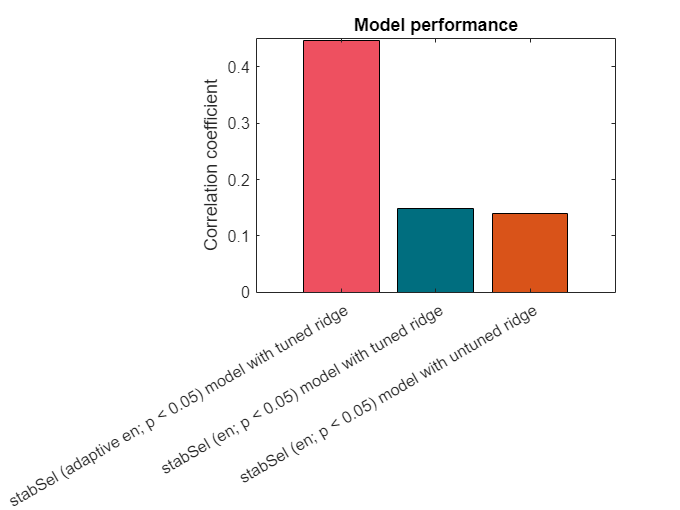

% Create barcharts for performance
b=bar(categorical({'stabSel (en; p < 0.05) model with untuned ridge','stabSel (en; p < 0.05) model with tuned ridge','stabSel (adaptive en; p < 0.05) model with tuned ridge'}),[r5 r7 r8],'FaceColor','flat');
b.CData(1,:) = ([238 80 96])/255;
b.CData(2,:) = ([0 110 127])/255;
b.CData(3,:) = ([0.8510 0.3255 0.0980]);
title('Model performance')
ylabel('Correlation coefficient')

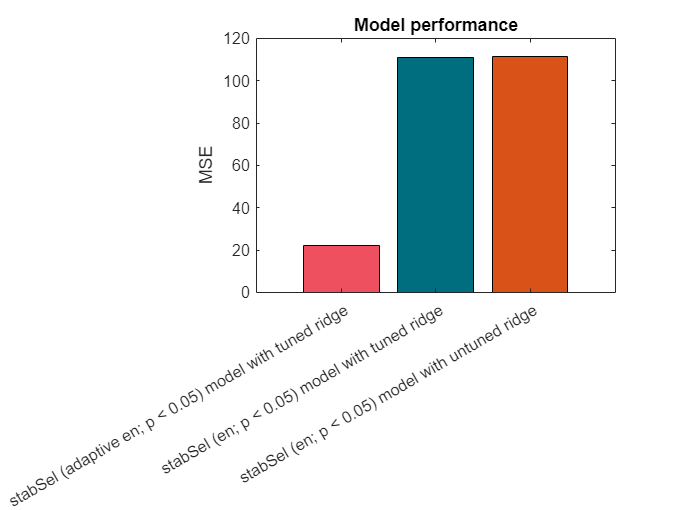

b=bar(categorical({'stabSel (en; p < 0.05) model with untuned ridge','stabSel (en; p < 0.05) model with tuned ridge','stabSel (adaptive en; p < 0.05) model with tuned ridge'}),[mse5 mse7 mse8],'FaceColor','flat');
b.CData(1,:) = ([238 80 96])/255;
b.CData(2,:) = ([0 110 127])/255;
b.CData(3,:) = ([0.8510 0.3255 0.0980]);
title('Model performance')
ylabel('MSE')

# Final notes-------------------------------------------------------------------------------------------------------------------------------

I will continue updating this tutorial with other examples, using other selection algorithms available in stabSel. If you are interested in more complex modeling of stability selected features, please see Tutorial2.mlx. While this tutorial covers a classification problem, all you need to do is substitute the classification algorithm for the corresponding regression function in matlab. For example, that tutorial covers: linear and nonlinear SVMs, k-NN classification, decision trees, random forests, and bayesian optimization instead of standard grid search. In order to perform regression, you would carry over the same arguments but replace the call to fitcsvm.m with fitrsvm.m, fitcensemble.m with fitrensemble.m, and fitctree.m with fitrtree.m.

As a final note, in hindsight, the dataset I have selected here is not optimal for feature selection. I mentioned this previously to be the case because it's high dimensional in the n >> p sense instead of p >> n. However, there is another reason it is not well suited to the task at hand...it has actually been preprocessed (quite well) for us already! The variables we have here are the outputs from a components analysis. While methods like PCA can still produce noise components, they are often robust (dimensionality reduction is an arguably worse alternative to feature selection), and there are no such components here. Evidence for this comes from the fact that you will get remarkably high performance without feature selection at all, for example, by running a simple OLS linear regression model in our 8-fold cross validation scheme (r = ~0.42). If you do try to tune the SVR model in example 4, you will see that you can approach the same level of performance with stability selection, suggesting that you can still use feature selection to build a model that is just as succesful, but substantially simpler. In most application settings where you're not trying to wrangle your features using multiple opposing methods, stability selection will not just simplify your model but also make it better (provided you spend some time properly implementing it). 

For original method and details of stability selection, see: Meinshausen, N., & Bühlmann, P. (2010). Stability selection. Journal of the Royal Statistical Society: Series B (Statistical Methodology), 72(4), 417-473.